# Data Preparation

clc
clear all
close all
rng(0)

A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
pinvA = pinv(A);
m = size(A, 2);
N = null(A, 'rational');
pinvN = pinv(N);

# Normalization parameters

To know the absolute limits on $i_{\varepsilon }$ and $i_B$, it is possible to sample points of randomly generated vectors of $i_{\textrm{xy}}$ and knowing $i_B =\textrm{pinv}\left(A\right)\cdot i_{\textrm{xy}}$, $i_z =i_s -i_B$ and $i_{\varepsilon \;} =\textrm{pinv}\left(N\right)\cdot i_z$

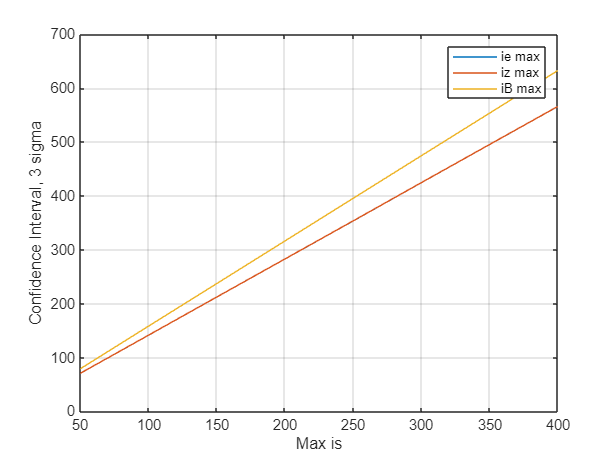

is_values = [50, 100, 150, 250, 300, 350, 400];
n_experiments = length(is_values);
n_samples = 1000000;
y1 = zeros(n_experiments, 1);
y2 = zeros(n_experiments, 1);
y3 = zeros(n_experiments, 1);

for idx = 1:n_experiments
    % Arcsine distribution for cluster currents
    is = sin(2*pi*rand(9, n_samples))*is_values(idx);

    % Calculation of external currents
    ixy = A*is;
    % Calculation of basic currents
    iB = pinvA*ixy;
    % Confidence interval of basic currents
    iB_max = std(iB(:))*3;
    % iB_max = max(abs(iB(:)));
    % Calculation of circulating currents
    iz = is - iB;
    % Confidence interval of circulating currents
    iz_max = std(iz(:))*3;
    
    % Calculation of linearly independent currents
    ie = pinvN*iz;
    % Confidence interval of linearly independent currents
    ie_max = std(ie(:))*3;
    % ie_max = max(abs((ie(:))));

    y1(idx) = ie_max;
    y2(idx) = iz_max;
    y3(idx) = iB_max;
end
figure
plot(is_values, y1)
hold on
plot(is_values, y2)
plot(is_values, y3)
hold off
xlabel("Max is")
ylabel("Confidence Interval, 3 sigma")
legend('ie max', 'iz max', 'iB max')
grid on



idx = 4;
x_bias = [ones(n_experiments, 1), is_values'];

beta = pinv(x_bias'*x_bias)*x_bias'*y1

beta =    -0.0284
    1.4144


ie_max = beta'*[1; is_values(idx)]

ie_max = 353.5621

ie_max = y1(idx)

ie_max = 353.3280


beta = pinv(x_bias'*x_bias)*x_bias'*y2

beta =    -0.0558
    1.4146


iz_max = beta'*[1; is_values(idx)]

iz_max = 353.5896

iz_max = y2(idx)

iz_max = 353.4193


beta = pinv(x_bias'*x_bias)*x_bias'*y3

beta =     0.0552
    1.5807


iB_max = beta'*[1; is_values(idx)]

iB_max = 395.2333

iB_max = y3(idx)

iB_max = 395.2787


% *En el caso de las corrientes linealmente independientes, la maxima es
% aproximadamente ie_max=1.42*Is_max. Por esto se normalizará la salida de
% la red correspondiente al vector ie, por 1.5*Is_max.
% *Para Las corrientes circulantes, la máxima pareciera ser igual que las
% linealmente independiente.
% *Mientras que en el caso de las corrientes basicas, la maxima es
% aproximadamente iB_max=1.58*Is_max. Por esto se normalizará la entrada de
% la red correspondiente al vector iB, por 1.6*Is_max.

Input/outputs limits

Ax = 7000;
Ay = 5000;
Is_max = 250;
C = 20e-3;
Von_max = (Ax+Ay)/2

Von_max = 6000

vc_ref = (Ax+Ay)*1.5

vc_ref = 18000


E = (C/2/4)*(vc_ref)^2 *1.1  % Capacitor energy

E = 8.9100e+05

VB = (Ax+Ay)                 % Branch voltages

VB = 12000

IB = 1.6*Is_max              % Basic currents

IB = 400

IE = 1.5*Is_max              % Linear independet currents

IE = 375


Xmax = [E*ones(9, 1); VB*ones(9, 1); IB*ones(9, 1)];
Ymax = [IE*ones(4, 1); Von_max];

# Load data from random data generator

load('bufferPOC.mat', 'buffer');
buffer = buffer';
Nbuffer_variables = size(buffer, 1)

Nbuffer_variables = 32

Nsamples = size(buffer, 2)

Nsamples = 100000


env = classM3C;
Ninputs = env.getObservationInfo.Dimension(1)

Ninputs = 27

Noutputs = env.getActionInfo.Dimension(1)

Noutputs = 5


X = buffer(1:27, :); size(X)

ans =           27      100000


Y = buffer(28:32, :); size(Y)

ans =            5      100000


# Preprocessing

Input/output sizes (MUST FIT WITH THE BUFFER SIZE)

[Ninputs, Nsamples] = size(X)

Ninputs = 27

Nsamples = 100000

[Noutputs, Nsamples] = size(Y)

Noutputs = 5

Nsamples = 100000

Normalization

X = X ./ Xmax;
Y = Y ./ Ymax;

Transform to dlarray

dlX = dlarray(X, 'CB');
dlY = dlarray(Y, 'CB');

Training/validation split

cv = cvpartition(Nsamples, 'HoldOut', 0.2);
idx_tr = training(cv);
idx_val = test(cv);

X_tr = X(:, idx_tr);
Y_tr = Y(:, idx_tr);
X_val = X(:, idx_val);
Y_val = Y(:, idx_val);

dlX_tr = dlX(:, idx_tr);
dlY_tr = dlY(:, idx_tr);
dlX_val = dlX(:, idx_val);
dlY_val = dlY(:, idx_val);

# Exploratory data analysis

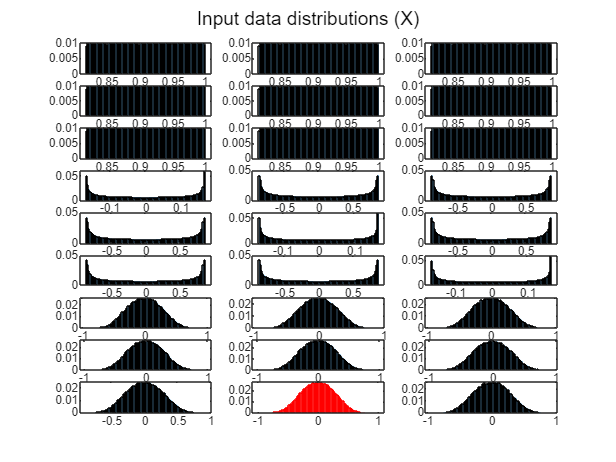

n_cols = 3;

figure
for idx = 1:Ninputs
    subplot(ceil(Ninputs / n_cols), n_cols, idx);
    if or(min(X(idx, :))<-1, max(X(idx, :))>1)
        histogram(X(idx, :), 100, 'Normalization', 'probability', 'FaceColor', 'red', 'EdgeColor', 'red');
    else
        histogram(X(idx, :), 100, 'Normalization', 'probability');
    end
    % title(['X', num2str(idx)]);
    % ylabel('Freq');
end
sgtitle('Input data distributions (X)')

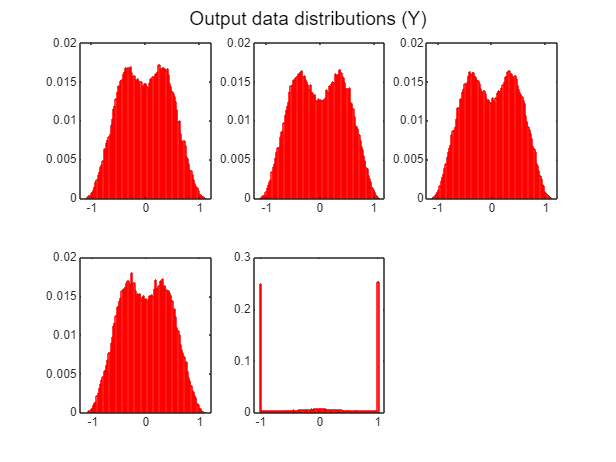


figure
for idx = 1:Noutputs
    subplot(ceil(Noutputs / n_cols), n_cols, idx)
    if or(min(Y(idx, :))<-1, max(Y(idx, :))>1)
        histogram(Y(idx, :), 100, 'Normalization', 'probability', 'FaceColor', 'red', 'EdgeColor', 'red')
    else
        histogram(Y(idx, :), 100, 'Normalization', 'probability')
    end
    % title(['Y', num2str(idx)])
    % ylabel('Freq')
end
sgtitle('Output data distributions (Y)')

# Sequencial data

% Nwindow = 10;
% 
% Nseq = Nsamples - Nwindow + 1;
% 
% Xseq = cell(Nseq, 1);
% Yseq = cell(Nseq, 1);
% 
% for i = 1:Nseq
%     Xseq{i} = X(:, i:(i + Nwindow - 1));
%     Yseq{i} = Y(:, i + Nwindow - 1);
% end
% 
% Xmat = zeros(Ninputs, Nwindow, Nseq);
% Ymat = zeros(Noutputs, Nseq);
% 
% for i = 1:Nseq
%     Xmat(:, :, i) = Xseq{i};
%     Ymat(:, i) = Yseq{i};
% end
% 
% dlXseq = dlarray(Xmat, 'CTB');
% dlYseq = dlarray(Ymat, 'CB');

Train/validation split

% cv = cvpartition(size(dlYseq, 2), 'HoldOut', 0.2);
% 
% idx_tr = training(cv);
% idx_val = test(cv);
% 
% dlXseq_tr = dlXseq(:, idx_tr, :);
% dlYseq_tr = dlYseq(:, idx_tr);
% dlXseq_val = dlXseq(:, idx_val, :);
% dlYseq_val = dlYseq(:, idx_val);

# Dimensionality reduction for state space visualization

## PCA

Input

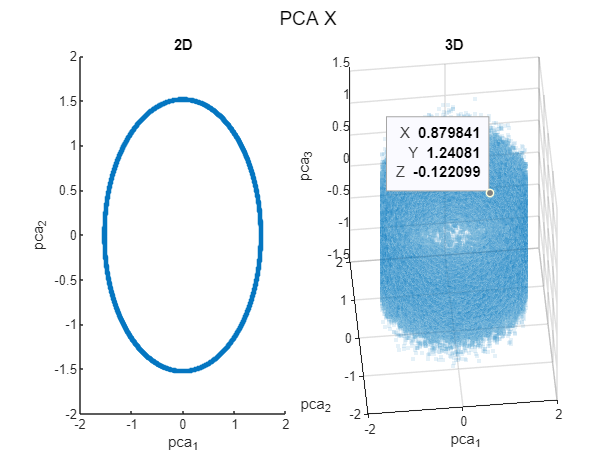

[coeff, score, latent] = pca(X');

figure
subplot(1, 2 ,1)
scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
title('2D');
xlabel('pca_1');
ylabel('pca_2');

subplot(1, 2, 2)
scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
title('3D');
xlabel('pca_1');
ylabel('pca_2');
zlabel('pca_3');

sgtitle('PCA X')

Output

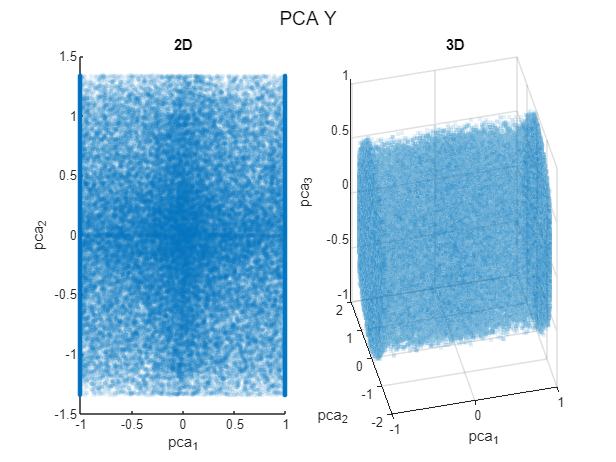

[coeff, score, latent] = pca(Y');

figure
subplot(1, 2, 1)
scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
title('2D');
xlabel('pca_1');
ylabel('pca_2');

subplot(1, 2, 2)
scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
title('3D');
xlabel('pca_1');
ylabel('pca_2');
zlabel('pca_3');

sgtitle('PCA Y')

## Clustering in reduced space

% Reducir dimensionalidad con PCA
num_dims = 3; % Dimensiones para clustering
% [coeff, score, latent] = pca(X');
[coeff, score, latent] = pca(Y');
X_reduced = score(:, 1:num_dims); % Usar las primeras 'num_dims' componentes principales

% Clustering en el espacio reducido
n_clusters = 5; % Número de clusters
epsilon = 0.13;  % Radio máximo para DBSCAN
minPts = 5;     % Mínimo número de puntos para DBSCAN

% K-means clustering
[idx_kmeans, C_kmeans] = kmeans(X_reduced, n_clusters, 'Replicates', 10);


% DBSCAN clustering
idx_dbscan = dbscan(X_reduced, epsilon, minPts);

% GMM clustering
gmm = fitgmdist(X_reduced, n_clusters, 'RegularizationValue', 1e-5);

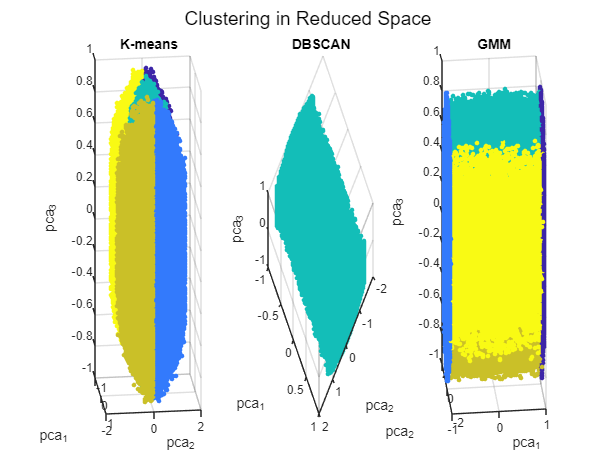

idx_gmm = cluster(gmm, X_reduced);

% Visualización de Clusters en el Espacio Reducido
figure

% subplot(3, 1, 1)
subplot(1, 3, 1)
scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_kmeans, 'filled');
title('K-means');
xlabel('pca_1');
ylabel('pca_2');
zlabel('pca_3');

% subplot(3, 1, 2)
subplot(1, 3, 2)
scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_dbscan, 'filled');
title('DBSCAN');
xlabel('pca_1');
ylabel('pca_2');
zlabel('pca_3');

% subplot(3, 1, 3)
subplot(1, 3, 3)
scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_gmm, 'filled');
title('GMM');
xlabel('pca_1');
ylabel('pca_2');
zlabel('pca_3');

sgtitle('Clustering in Reduced Space');

## Clustering in original space

n_clusters = 5; % Número de clusters
epsilon = 0.1;  % Radio máximo para DBSCAN
minPts = 5;     % Mínimo número de puntos para DBSCAN

% K-means
[idx_kmeans, C_kmeans] = kmeans(Y', n_clusters, 'Replicates', 10);


% DBSCAN
idx_dbscan = dbscan(Y', epsilon, minPts);

% GMM
gmm = fitgmdist(Y', n_clusters, 'RegularizationValue', 1e-5);

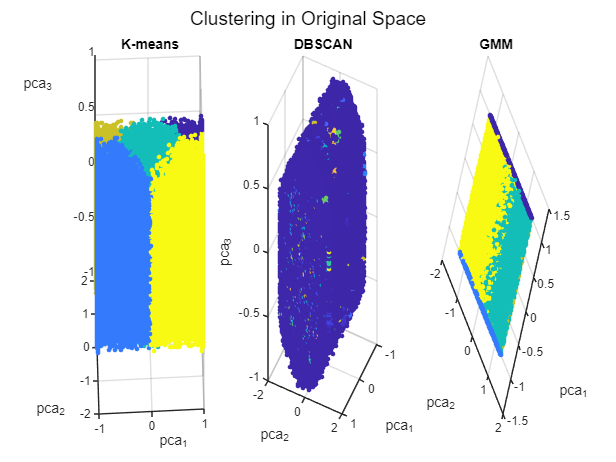

idx_gmm = cluster(gmm, Y');

% PCA
num_dims = 3;
[coeff, score, latent] = pca(Y');
X_reduced = score(:, 1:num_dims);

figure

% K-means
subplot(1, 3, 1)
scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_kmeans, 'filled');
title('K-means'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');

% DBSCAN
subplot(1, 3, 2)
scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_dbscan, 'filled');
title('DBSCAN'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');

% GMM
subplot(1, 3, 3)
scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_gmm, 'filled');
title('GMM'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');

sgtitle('Clustering in Original Space');

## UMAP

% pyenv('Version', '3.12', 'ExecutionMode', 'OutOfProcess')
% system('pip install umap-learn')
% 
% code_Y = [
%           "import umap"
%           "import numpy as np"
%           "reducer_X = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=2)"
%           "Xumap = reducer_X.fit_transform(np.transpose(X))"
%          ];
% code_X = [
%           "import umap"
%           "import numpy as np"
%           "reducer_Y = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=2)"
%           "Yumap = reducer_Y.fit_transform(np.transpose(Y))"
%          ];
% 
% Xumap = double(pyrun(code_X, 'Xumap', X=X));
% Yumap = double(pyrun(code_Y, 'Yumap', Y=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter(Xumap(:, 1), Xumap(:, 2), 15, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); grid on;
% 
% subplot(1, 2, 2);
% scatter(Yumap(:, 1), Yumap(:, 2), 15, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); grid on;